# Decryption

clc;
clear;
close all;

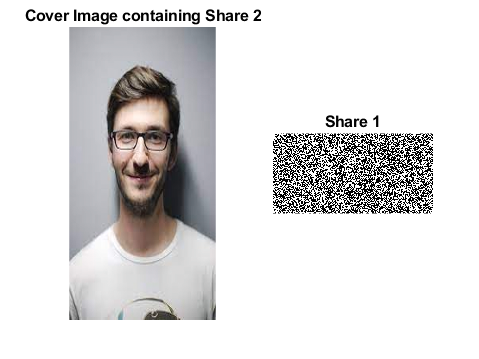

% Read the images
face = imread('face.tif');
share1 = imread('Share1.tif');
share1 = imbinarize(share1);

figure;subplot(121);imshow(face);title('Cover Image containing Share 2'); 
       subplot(122);imshow(share1);title('Share 1');

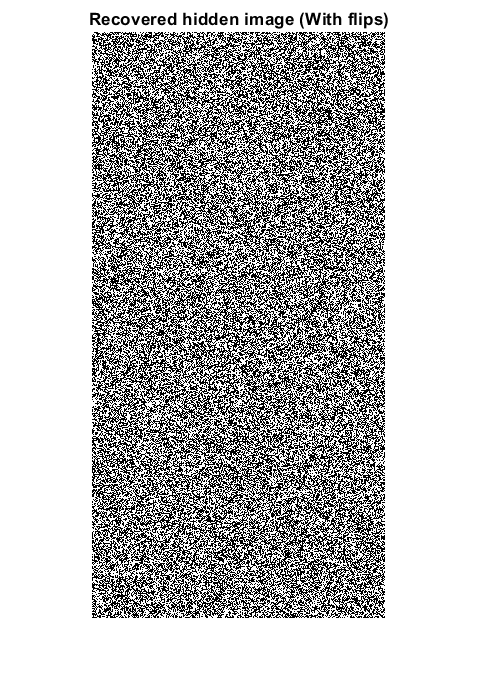

employee = 123456789;
tic;
x =  rem(employee,3)+1;
% inverse watermarking

layer = face(:,:,x);
a=mod(layer,2);
b=zeros(600,300);
for x=1:600
    for y=1:300
        if(a(x,y)==1)
            b(x,y)=255;
        end
    end
end
recImg=imbinarize(b);
t1 = toc;
figure
imshow(recImg); % hidden image
title('Recovered hidden image (With flips)')

tic
s = rng(employee)

s = struct with fields:
     Type: 'twister'
     Seed: 123456789
    State: [625×1 uint32]


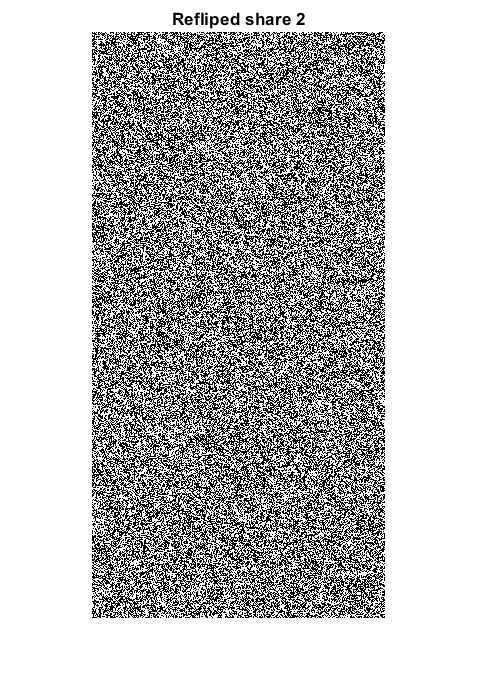


a = randi([0 1],600,1);

share2_flip = zeros(600,300);
for i = 1:size(recImg,1)
    if a(i) ==1
        share2_flip(i,1:end) = fliplr(recImg(i,1:end));
    else
        share2_flip(i,1:end) = recImg(i,1:end);
    end
end
share2 = imbinarize(share2_flip);
t2 = toc;
figure;imshow(share2_flip);title(['Refliped share 2']); 

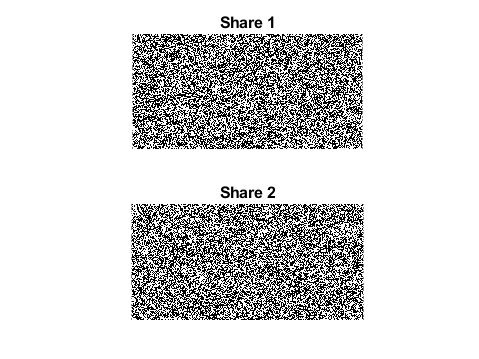



share2 = reshape(share2,[size(share2,2),size(share2,1)]);


figure;subplot(211);imshow(share1);title('Share 1'); 
       subplot(212);imshow(share2);title('Share 2');

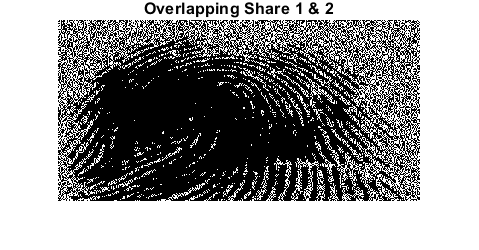

% Decrypting the shares
tic;
share12 = bitor(share1, share2);
share12 = ~share12;



s = [300 , 300];
shareop = zeros(s);
for i = 1:s(1)
for j = 1:s(2)
    a = share12(i,(2*j-1):(2*j));
    shareop(i,j) = max(a);
end
end
t3 = toc;
figure;imshow(share12);title('Overlapping Share 1 & 2');

disp("VCS Decryption")

VCS Decryption


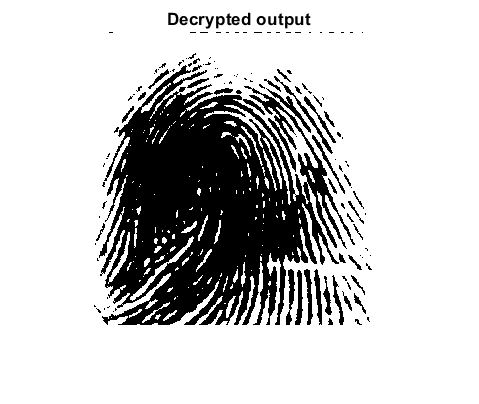


figure;imshow(shareop);title('Decrypted output');

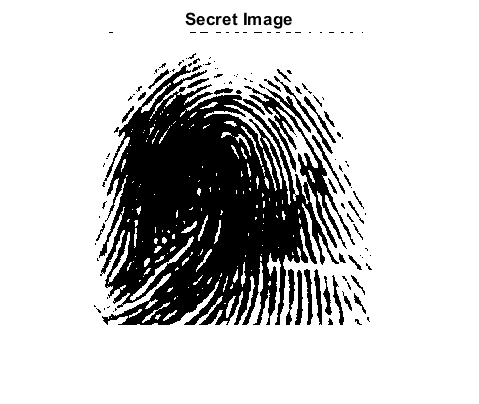


inImg = imread('102_3.tif');
inImg = imbinarize(inImg);
figure;imshow(inImg);title('Secret Image');



imwrite(shareop,'decrypted.tif');


tic
thresh = xor(shareop,inImg);
thresh = sum(sum(thresh));
if thresh < 0.1*size(inImg,1)*size(inImg,2)
    disp("Authenticated.")
end

Authenticated.


t4 = toc;
time  = t1 + t2 + t3+ t4;
disp("Time taken for Decryption")

Time taken for Decryption


disp(time)

    0.2437

